# HMM Analysis

clear % clear all variables in the workspace
close all % close any figure windows that might be open
clc

addpath(genpath('./lib'))

Figflag = 0;
cmap_temp = [[0 0.4470 0.7410];[0.8500 0.3250 0.0980];[0.9290 0.6940 0.1250];[0.4940 0.1840 0.5560]];

## Part 1: Add working path and load the data

We will initialize the paths that are used later

% Make figure path
FigPath = ['./figure/embryo6/'];
mkdir(FigPath)

Now, load all the data

load('./data/hmm_input_output.mat')

Specify some parameters

numParticle = length(hmm_input_output);
TimeOffset = 11.31;

% Specify the bins we want to plot
%binRange = 61:66; % 61-66 
binRange = 61:66; % new

%bin number
len = 15;

%time range to plot
TimeMin = 300;
TimeMax = 1800;

offset = 1.8E5;
%edges = linspace(2.6E5,4.4E5,len+1);
edges = linspace(2.6E5-offset,4.4E5-offset,len+1);

## Part 2: Fliter traces including quality control

First, we want to filter the traces based on SetID

dataID = 2; % We want to analyze "optoknirps_new_embryo6"
SetID_all = [hmm_input_output(:).SetID]; % SetID for all the traces
%TraceIndex = find(SetID_all == dataID); % Trace index that we will analyze

Then, we can assign the traces to each AP bin

APbinID = linspace(0,100,101);
APPosition_mean = zeros(numParticle,1);

for i = 1:numParticle
    APPosition_mean(i) = mean(hmm_input_output(i).APPosition);
end

APbinData = discretize(APPosition_mean,APbinID);

Quality control: Only keep the traces that is continuous across specified time range

QualityFlag = zeros(numParticle,1);

LeftBound = 5;
RightBound = 15;

for i = 1:numParticle
    MinTime = hmm_input_output(i).Time(1)/60-TimeOffset;
    MaxTime = hmm_input_output(i).Time(end)/60-TimeOffset;

    if (MinTime<LeftBound) && (MaxTime>RightBound)
        QualityFlag(i) = 1;
    else
        QualityFlag(i) = 0;
    end
end

## Part 3: Compile promoter states

First, we will do this for the full bin range

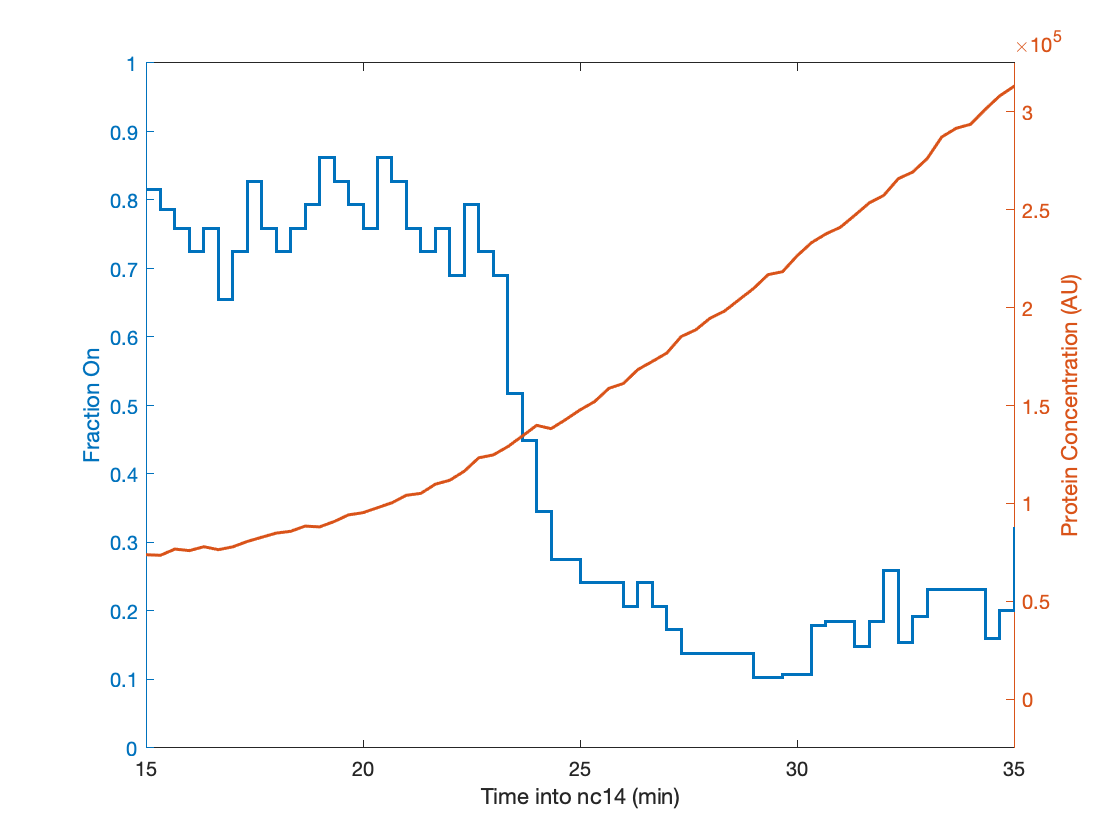

TimeRange = 0:20:2400;

% Initialize array for storage
TotalOn = zeros(1,length(TimeRange));
TotalTrace = zeros(1,length(TimeRange));
ProteinSum = zeros(1,length(TimeRange));
SpotSum = zeros(1,length(TimeRange));

TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag');

% compile promoter states and protein concentration
for i = TraceIndex
    TimePoint = hmm_input_output(i).Time;
    PromoterState = hmm_input_output(i).PromoterState;
    NuclearConc = hmm_input_output(i).NuclearKnirps-offset;
    SpotFluo = hmm_input_output(i).SpotFluorescence;
    
    for j = 1:length(TimePoint)
        Index = find(TimeRange==TimePoint(j));
        % compile promoter states
        if PromoterState(j)>2
            TotalOn(Index) = TotalOn(Index)+1;
            TotalTrace(Index) = TotalTrace(Index)+1;
        else
            TotalTrace(Index) = TotalTrace(Index)+1;
        end
        % compile protein concentration
        ProteinSum(Index) = ProteinSum(Index)+NuclearConc(j);
        SpotSum(Index) = SpotSum(Index)+SpotFluo(j);
    end
    
end

FractionOn = TotalOn./TotalTrace;
SpotAvr = SpotSum./TotalTrace;
ProteinAvr = ProteinSum./TotalTrace;

fig = figure;
yyaxis left
stairs(TimeRange/60,FractionOn,'LineWidth',1.5)
ylabel('Fraction On')
ylim([0 1])
yyaxis right
plot(TimeRange/60,ProteinAvr,'LineWidth',1.5)
ylabel('Protein Concentration (AU)')
ylim([2E5 5.5E5]-2.25E5)

xlim([15,35])
xlabel('Time into nc14 (min)')

We can plot "input-output" function for it

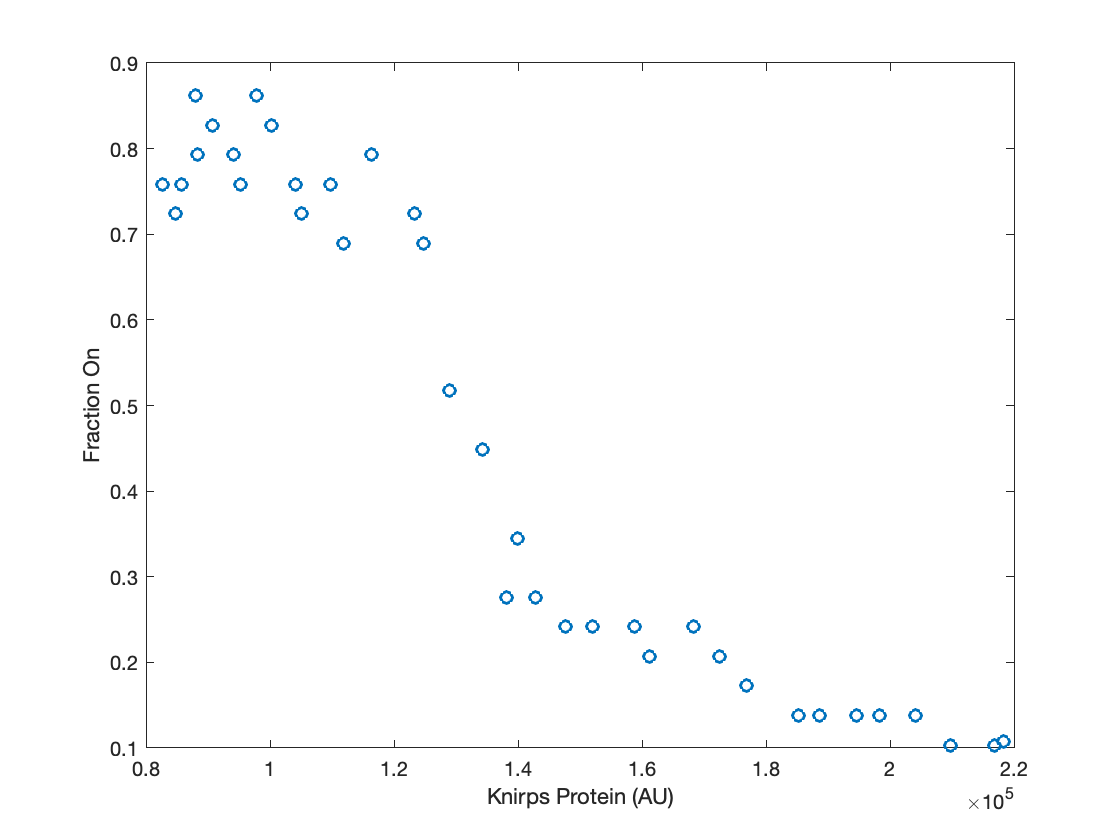

TimePlotRange = 54:90;

% generate fit
%fitname = 'a*x^n/(K^n+x^n)';

% without c
%[io_fit_full,gof_full] = fit(x(:),y(:),fitname,'StartPoint',[9e5,8e4,0],'Lower',[0,0,0]);


Fig = figure;
plot(ProteinAvr(TimePlotRange),FractionOn(TimePlotRange),'o','LineWidth',1.5)
xlabel('Knirps Protein (AU)')
ylabel('Fraction On')

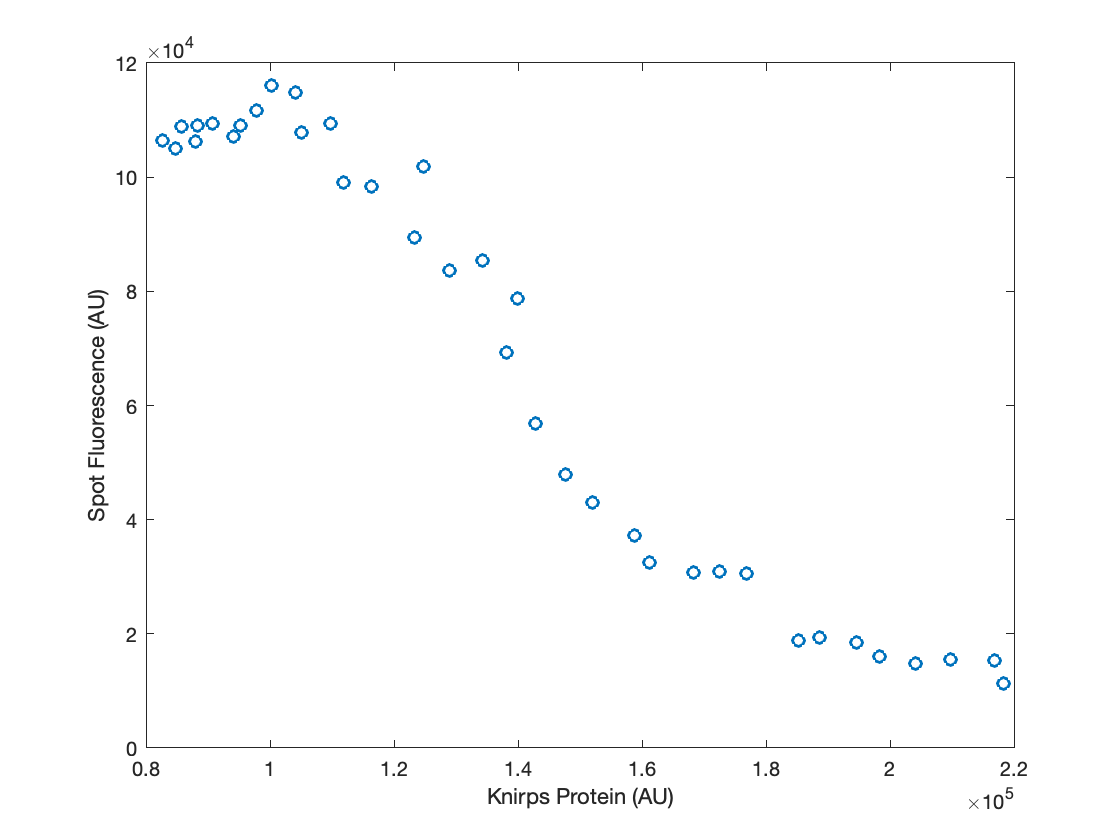

Fig = figure;
plot(ProteinAvr(TimePlotRange),SpotAvr(TimePlotRange),'o','LineWidth',1.5)
xlabel('Knirps Protein (AU)')
ylabel('Spot Fluorescence (AU)')

Next, we will calculate same value for different bins

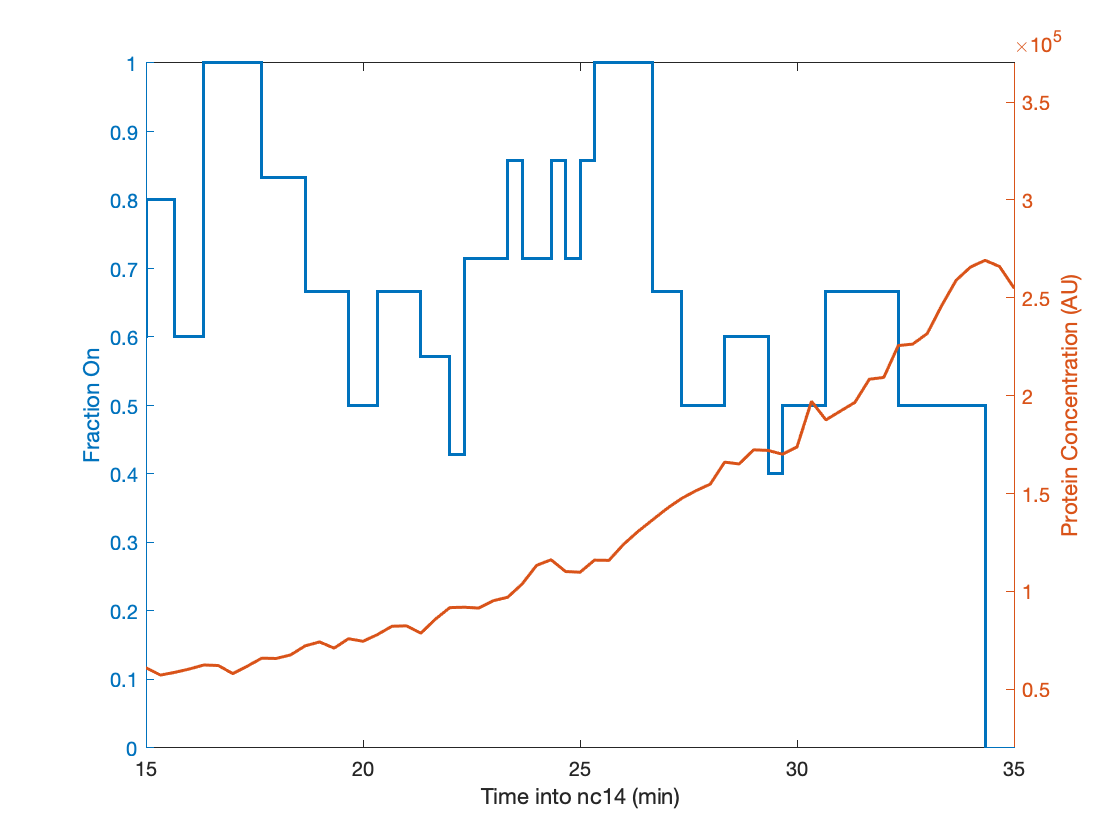

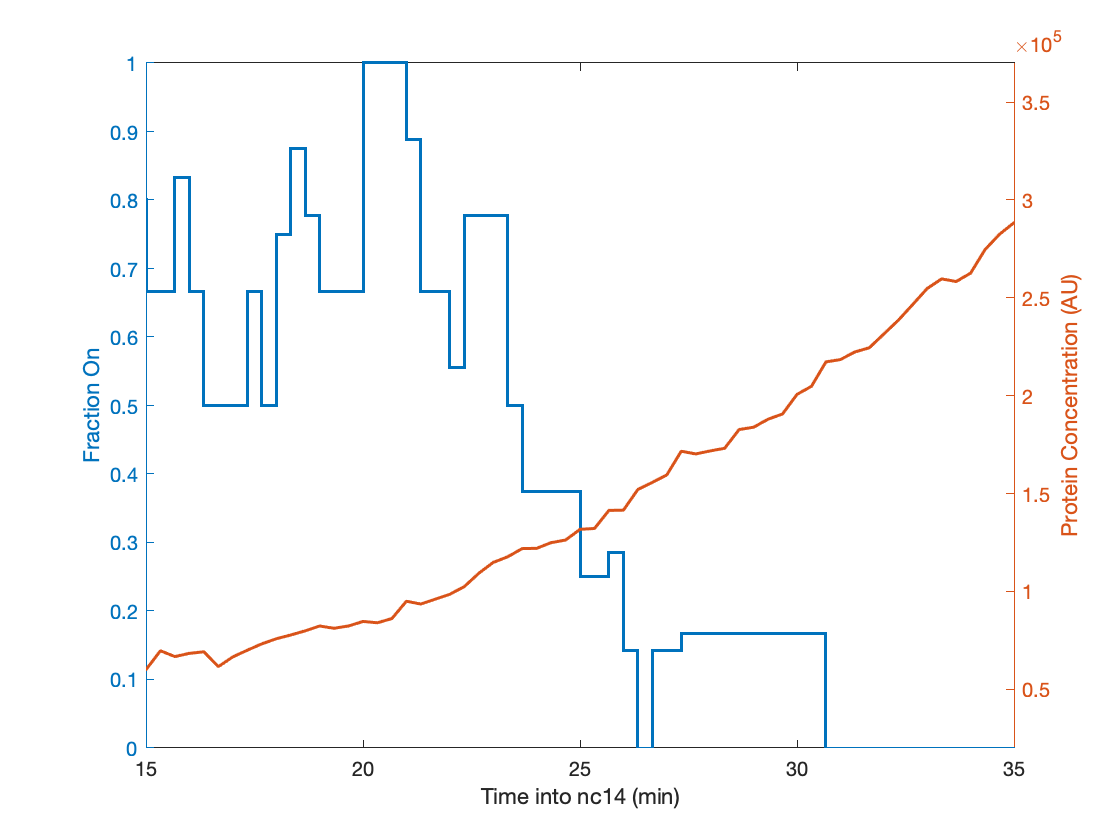

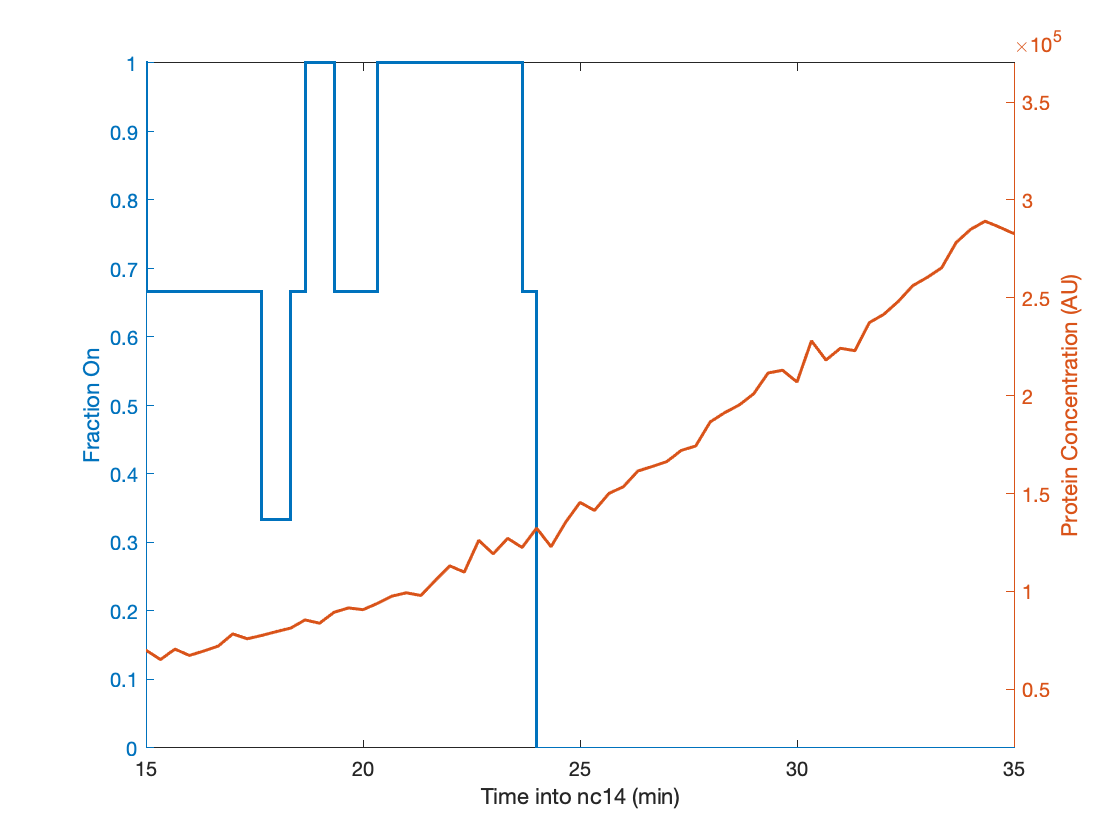

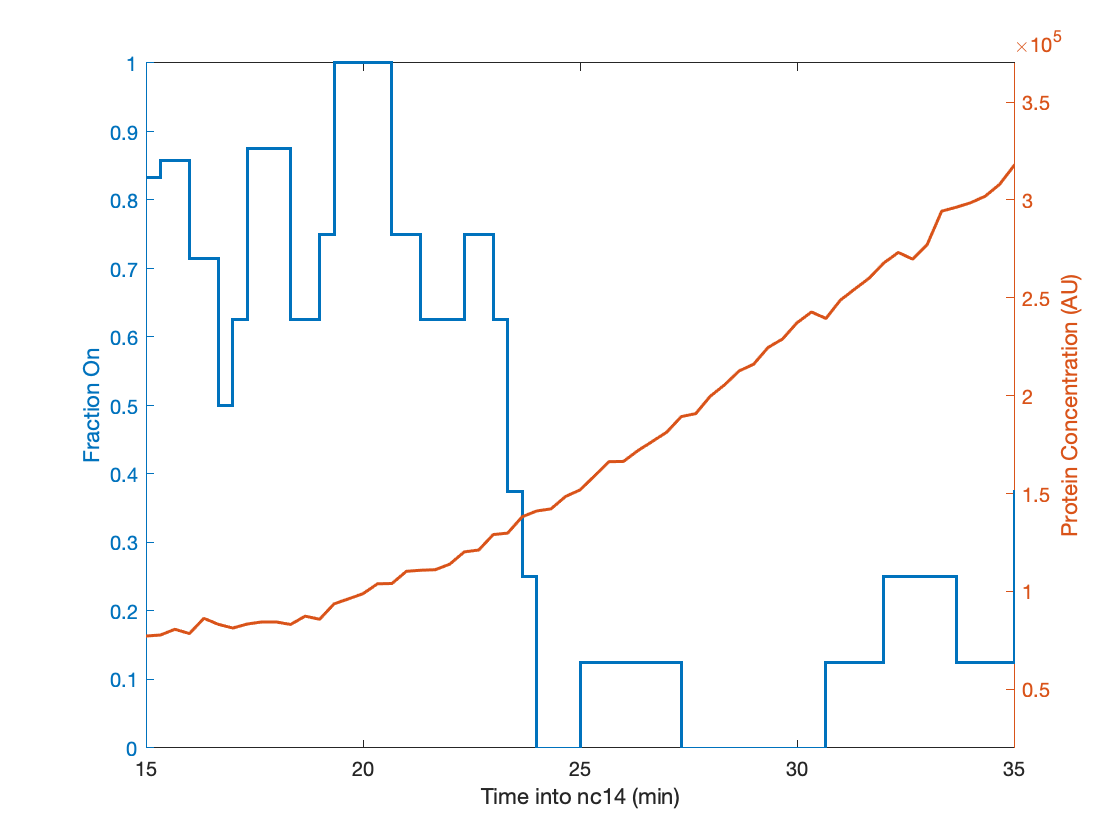

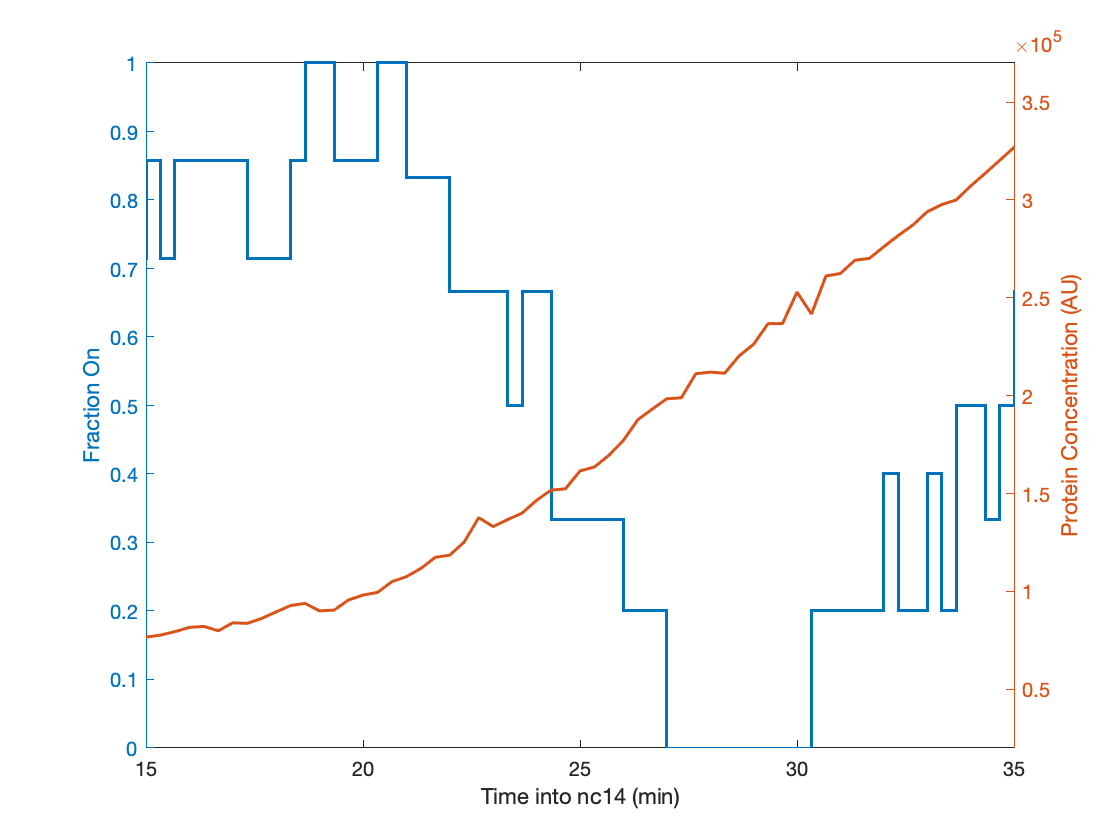

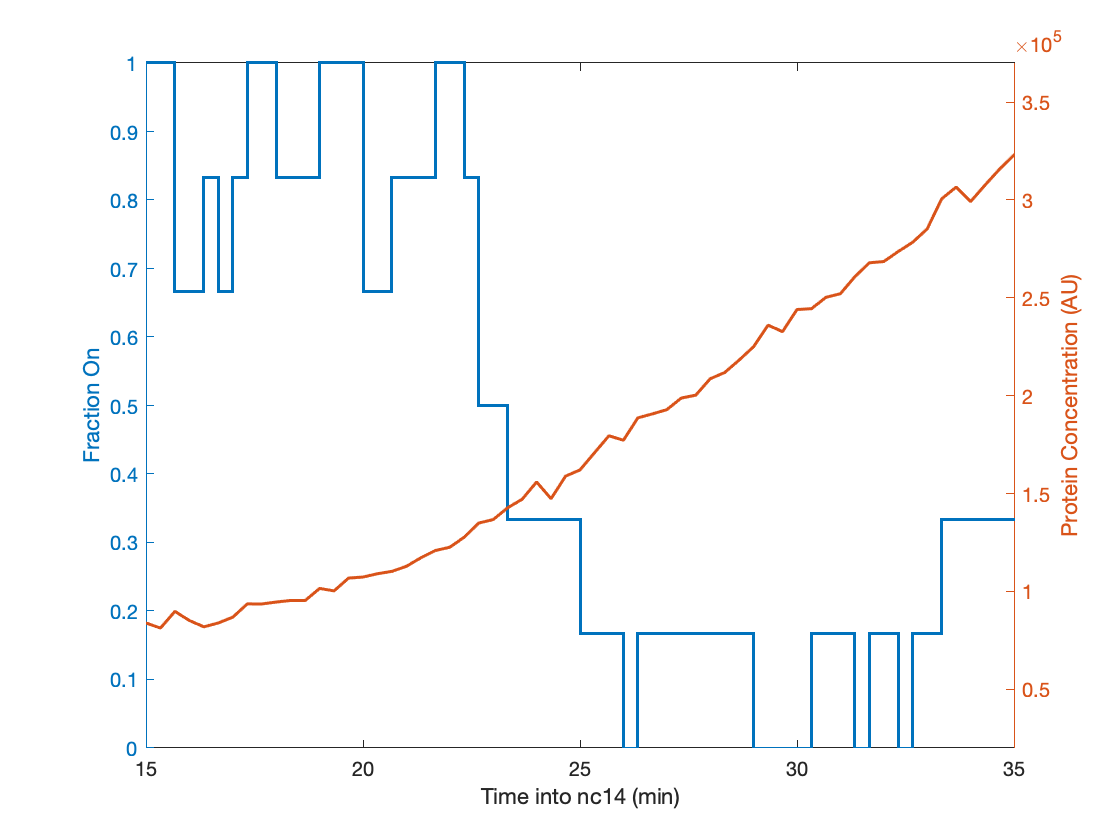

for i = binRange

    % Initialize array for storage
    TotalOn = zeros(1,length(TimeRange));
    TotalTrace = zeros(1,length(TimeRange));
    ProteinTrace = zeros(1,length(TimeRange));
    ProteinSum = zeros(1,length(TimeRange));
    
    TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,i)')); %& QualityFlag');
    
    % compile promoter states and protein concentration
    for j = TraceIndex
        TimePoint = hmm_input_output(j).Time;
        PromoterState = hmm_input_output(j).PromoterState;
        NuclearConc = hmm_input_output(j).NuclearKnirps-offset;
        
        for k = 1:length(TimePoint)
            Index = find(TimeRange==TimePoint(k));
            % compile promoter states
            if PromoterState(k)>2
                TotalOn(Index) = TotalOn(Index)+1;
                TotalTrace(Index) = TotalTrace(Index)+1;
            else
                TotalTrace(Index) = TotalTrace(Index)+1;
            end
            % compile protein concentration
            if ~isnan(NuclearConc(k))
                ProteinSum(Index) = ProteinSum(Index)+NuclearConc(k);
                ProteinTrace(Index) = ProteinTrace(Index)+1;
            end
        end
        
    end
    Fig = figure;
    yyaxis left
    stairs(TimeRange/60,TotalOn./TotalTrace,'LineWidth',1.5)
    ylabel('Fraction On')
    ylim([0 1])
    yyaxis right
    plot(TimeRange/60,ProteinSum./ProteinTrace,'LineWidth',1.5)
    ylabel('Protein Concentration (AU)')
    ylim([2E5 5.5E5]-offset)
    
    xlim([15,35])
    xlabel('Time into nc14 (min)')

end

Calculate input-output function from single particle traces

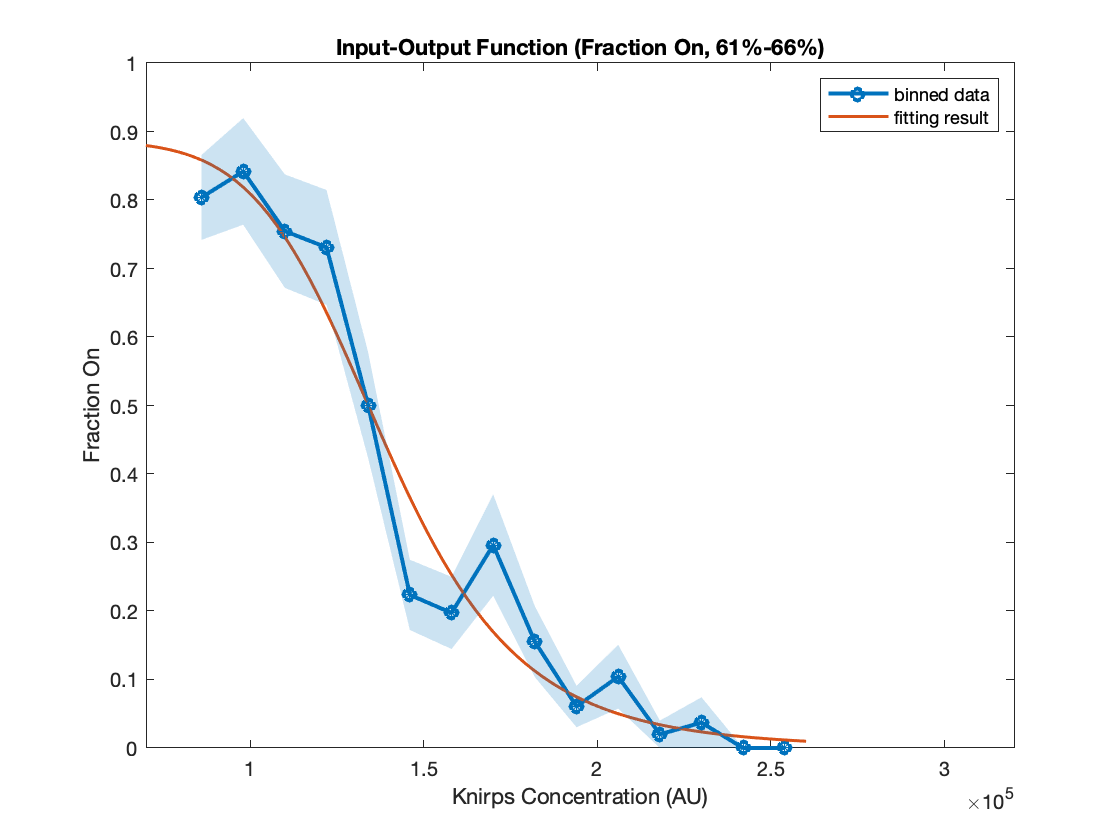

ProteinConc_all = [];
SpotFluo_all = [];
PromoterState_all = [];

TraceIndex = find((SetID_all == dataID) & (ismember(APbinData,binRange)') & QualityFlag');

for i = TraceIndex
    TimePoint = hmm_input_output(i).Time;
    for j = 1:length(TimePoint)
        if (TimePoint(j)<TimeMax) && (TimePoint(j)>TimeMin)
            ProteinConc_all = [ProteinConc_all hmm_input_output(i).NuclearKnirps(j)-offset];
            PromoterState_all = [PromoterState_all (hmm_input_output(i).PromoterState(j)>2)];
            SpotFluo_all = [SpotFluo_all hmm_input_output(i).SpotFluorescence(j)];
        end
    end
end

x = ProteinConc_all';
y = PromoterState_all';
ys = SpotFluo_all';

%edges = quantile(x,len-1);
%edges = [min(x) edges];edges = [edges max(x)]; % add zero and max to left and right hand side of the array
%edges = linspace(min(ProteinConc_all), max(ProteinConc_all),len+1);
[~,~,loc]=histcounts(x,edges);

yplot = accumarray(loc(loc>0),y(loc>0),[len 1])./accumarray(loc(loc>0),1,[len 1]);
yplots = accumarray(loc(loc>0),ys(loc>0),[len 1])./accumarray(loc(loc>0),1,[len 1]);
err = sqrt(accumarray(loc(loc>0),(y(loc>0)).^2,[len 1])./accumarray(loc(loc>0),1,[len 1]))./sqrt(accumarray(loc(loc>0),1,[len 1]));
errs = sqrt(accumarray(loc(loc>0),(ys(loc>0)).^2,[len 1])./accumarray(loc(loc>0),1,[len 1]))./sqrt(accumarray(loc(loc>0),1,[len 1]));

xmid = 0.5*(edges(1:end-1)+edges(2:end));


% generate fit
% specify fit type
fitname = 'a*K^n/(K^n+x^n)';
[io_fit,gof] = fit(xmid(:),yplot(:),fitname,'StartPoint',[3e5,0,0],'Lower',[0,0,0]);
[io_fits,gof] = fit(xmid(:),yplots(:),fitname,'StartPoint',[3e5,1E5,0],'Lower',[0,0,0]);

xRange = double(linspace(min(ProteinConc_all), max(ProteinConc_all)));

fig = figure;
plot(xmid,yplot,'-o','LineWidth',2)
hold on
plot(xRange,io_fit(xRange),'LineWidth',1.5)
boundedline(xmid, yplot, err,'-*','nan', 'gap','alpha','cmap', cmap_temp(1,:));
xlim([2.5E5 5E5]-offset)
ylim([0 1])
xlabel('Knirps Concentration (AU)')
ylabel('Fraction On')
title('Input-Output Function (Fraction On, 61%-66%)')

legend('binned data','fitting result')

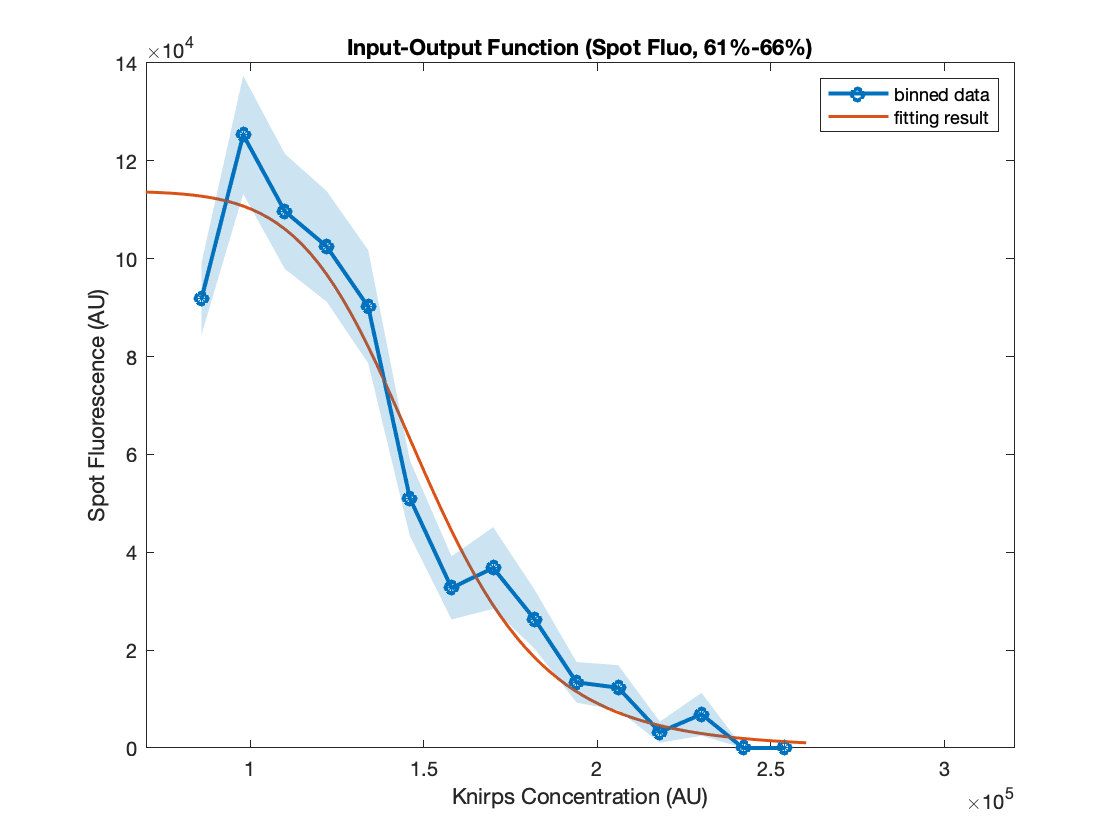

fig = figure;
plot(xmid,yplots,'-o','LineWidth',2)
hold on
plot(xRange,io_fits(xRange),'LineWidth',1.5)
boundedline(xmid, yplots, errs,'-*','nan', 'gap','alpha','cmap', cmap_temp(1,:));
xlim([2.5E5 5E5]-offset)
ylim([0 14E4])
xlabel('Knirps Concentration (AU)')
ylabel('Spot Fluorescence (AU)')
title('Input-Output Function (Spot Fluo, 61%-66%)')

legend('binned data','fitting result')

Is this consistant across two AP bins?

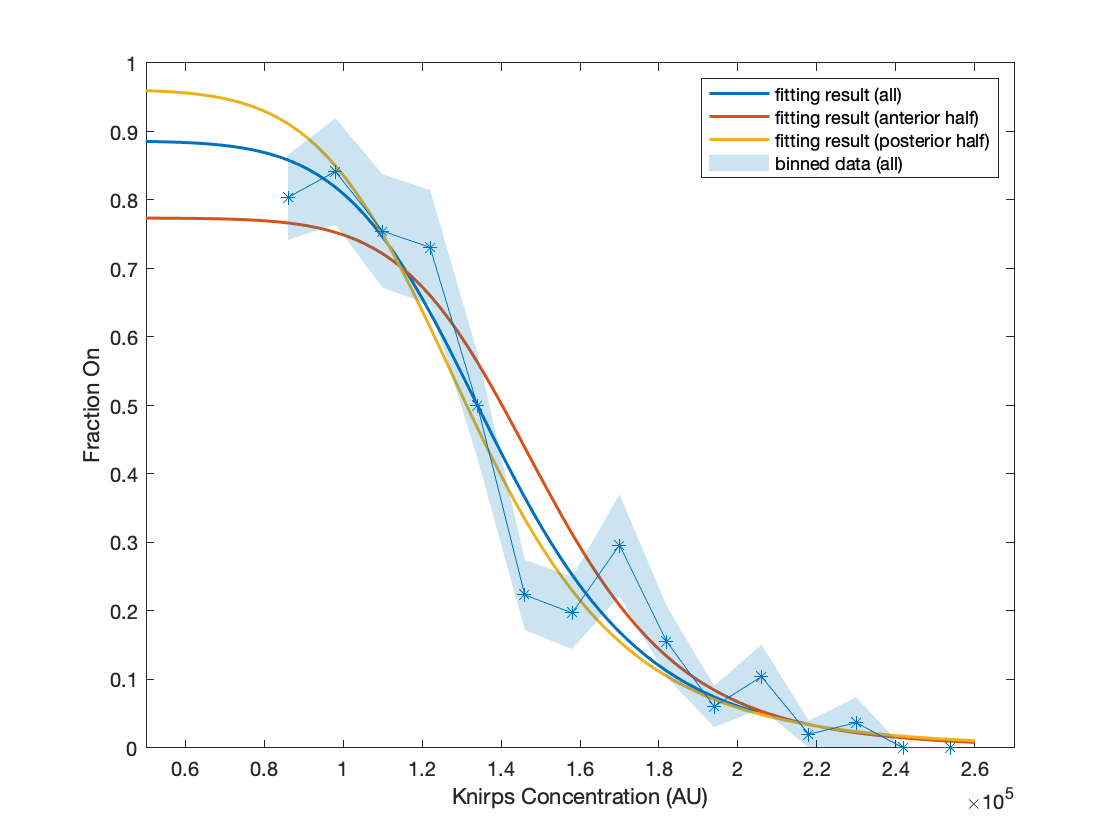

binRange_1 = 61:63;
binRange_2 = 64:66;

TraceIndex_1 = find((SetID_all == dataID) & (ismember(APbinData,binRange_1)') & QualityFlag');
TraceIndex_2 = find((SetID_all == dataID) & (ismember(APbinData,binRange_2)') & QualityFlag');

ProteinConc_1_all = [];
PromoterState_1_all = [];
ProteinConc_2_all = [];
PromoterState_2_all = [];

for i = TraceIndex_1
    for j = 1:length(TimePoint)
        if (TimePoint(j)<TimeMax) && (TimePoint(j)>TimeMin)
            ProteinConc_1_all = [ProteinConc_1_all hmm_input_output(i).NuclearKnirps(j)-offset];
            PromoterState_1_all = [PromoterState_1_all (hmm_input_output(i).PromoterState(j)>2)];
        end
    end
end

for i = TraceIndex_2
    for j = 1:length(TimePoint)
        if (TimePoint(j)<TimeMax) && (TimePoint(j)>TimeMin)
            ProteinConc_2_all = [ProteinConc_2_all hmm_input_output(i).NuclearKnirps(j)-offset];
            PromoterState_2_all = [PromoterState_2_all (hmm_input_output(i).PromoterState(j)>2)];
        end
    end
end

x1 = ProteinConc_1_all';
y1 = PromoterState_1_all';

x2 = ProteinConc_2_all';
y2 = PromoterState_2_all';

%edges = quantile(x,len-1);
%edges = [min(x) edges];edges = [edges max(x)]; % add zero and max to left and right hand side of the array
%edges = linspace(min(ProteinConc_all), max(ProteinConc_all),len+1);

[~,~,loc1]=histcounts(x1,edges);
[~,~,loc2]=histcounts(x2,edges);

yplot1 = accumarray(loc1(loc1>0),y1(loc1>0),[len 1])./accumarray(loc1(loc1>0),1,[len 1]);
err1 = sqrt(accumarray(loc1(loc1>0),(y1(loc1>0)).^2,[len 1])./accumarray(loc1(loc1>0),1,[len 1]))./sqrt(accumarray(loc1(loc1>0),1,[len 1]));
yplot2 = accumarray(loc2(loc2>0),y2(loc2>0),[len 1])./accumarray(loc2(loc2>0),1,[len 1]);
err2 = sqrt(accumarray(loc2(loc2>0),(y2(loc2>0)).^2,[len 1])./accumarray(loc2(loc2>0),1,[len 1]))./sqrt(accumarray(loc2(loc2>0),1,[len 1]));

xmid_new = 0.5*(edges(1:end-1)+edges(2:end));

% generate fit
% specify fit type
fitname = 'a*K^n/(K^n+x^n)';
[io_fit_1,gof] = fit(xmid_new(:),yplot1(:),fitname,'StartPoint',[3e5,0,0],'Lower',[0,0,0]);
[io_fit_2,gof] = fit(xmid_new(find(~isnan(yplot2)))',yplot2(find(~isnan(yplot2))),fitname,'StartPoint',[3e5,0,0],'Lower',[0,0,0]);
xRange = double(linspace(min(ProteinConc_all), max(ProteinConc_all)));

fig = figure;
plot(xRange,io_fit(xRange),'LineWidth',1.5)
hold on
plot(xRange,io_fit_1(xRange),'LineWidth',1.5)
plot(xRange,io_fit_2(xRange),'LineWidth',1.5)
boundedline(xmid, yplot, err,'-*','nan', 'gap','alpha','cmap', cmap_temp(1,:));

xlim([2.3E5 4.5E5]-offset)
ylim([0 1])
xlabel('Knirps Concentration (AU)')
ylabel('Fraction On')

legend('fitting result (all)','fitting result (anterior half)','fitting result (posterior half)','binned data (all)')

Is this consistant across three AP bins?

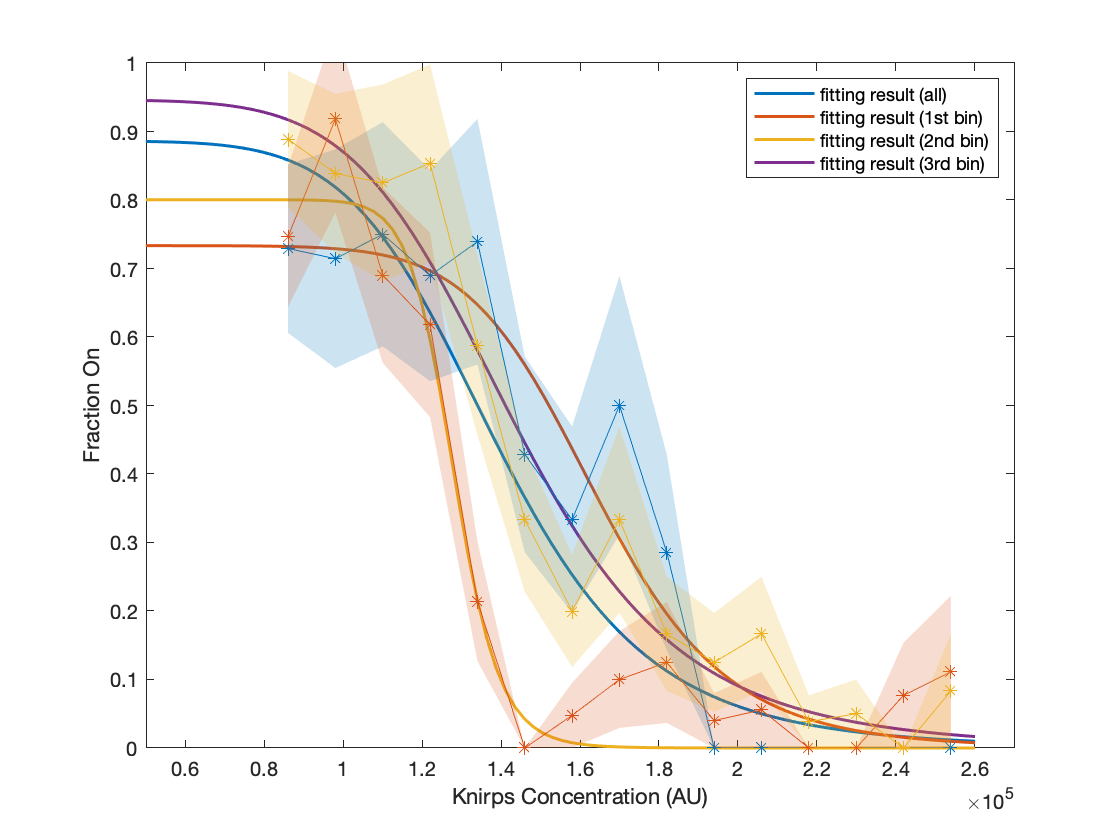

binRange_1 = 61:62;
binRange_2 = 63:64;
binRange_3 = 65:66;

TraceIndex_1 = find((SetID_all == dataID) & (ismember(APbinData,binRange_1)') & QualityFlag');
TraceIndex_2 = find((SetID_all == dataID) & (ismember(APbinData,binRange_2)') & QualityFlag');
TraceIndex_3 = find((SetID_all == dataID) & (ismember(APbinData,binRange_3)') & QualityFlag');

ProteinConc_1_all = [];
PromoterState_1_all = [];
ProteinConc_2_all = [];
PromoterState_2_all = [];
ProteinConc_3_all = [];
PromoterState_3_all = [];

for i = TraceIndex_1
    for j = 1:length(TimePoint)
        if (TimePoint(j)<TimeMax) && (TimePoint(j)>TimeMin)
            ProteinConc_1_all = [ProteinConc_1_all hmm_input_output(i).NuclearKnirps(j)-offset];
            PromoterState_1_all = [PromoterState_1_all (hmm_input_output(i).PromoterState(j)>2)];
        end
    end
end

for i = TraceIndex_2
    for j = 1:length(TimePoint)
        if (TimePoint(j)<TimeMax) && (TimePoint(j)>TimeMin)
            ProteinConc_2_all = [ProteinConc_2_all hmm_input_output(i).NuclearKnirps(j)-offset];
            PromoterState_2_all = [PromoterState_2_all (hmm_input_output(i).PromoterState(j)>2)];
        end
    end
end

for i = TraceIndex_3
    for j = 1:length(TimePoint)
        if (TimePoint(j)<TimeMax) && (TimePoint(j)>TimeMin)
            ProteinConc_3_all = [ProteinConc_3_all hmm_input_output(i).NuclearKnirps(j)-offset];
            PromoterState_3_all = [PromoterState_3_all (hmm_input_output(i).PromoterState(j)>2)];
        end
    end
end

x1 = ProteinConc_1_all';
y1 = PromoterState_1_all';

x2 = ProteinConc_2_all';
y2 = PromoterState_2_all';

x3 = ProteinConc_3_all';
y3 = PromoterState_3_all';

%edges = quantile(x,len-1);
%edges = [min(x) edges];edges = [edges max(x)]; % add zero and max to left and right hand side of the array
%edges = linspace(min(ProteinConc_all), max(ProteinConc_all),len+1);

[~,~,loc1]=histcounts(x1,edges);
[~,~,loc2]=histcounts(x2,edges);
[~,~,loc3]=histcounts(x3,edges);

yplot1 = accumarray(loc1(loc1>0),y1(loc1>0),[len 1])./accumarray(loc1(loc1>0),1,[len 1]);
err1 = sqrt(accumarray(loc1(loc1>0),(y1(loc1>0)).^2,[len 1])./accumarray(loc1(loc1>0),1,[len 1]))./sqrt(accumarray(loc1(loc1>0),1,[len 1]));
yplot2 = accumarray(loc2(loc2>0),y2(loc2>0),[len 1])./accumarray(loc2(loc2>0),1,[len 1]);
err2 = sqrt(accumarray(loc2(loc2>0),(y2(loc2>0)).^2,[len 1])./accumarray(loc2(loc2>0),1,[len 1]))./sqrt(accumarray(loc2(loc2>0),1,[len 1]));
yplot3 = accumarray(loc3(loc3>0),y3(loc3>0),[len 1])./accumarray(loc3(loc3>0),1,[len 1]);
err3 = sqrt(accumarray(loc3(loc3>0),(y3(loc3>0)).^2,[len 1])./accumarray(loc3(loc3>0),1,[len 1]))./sqrt(accumarray(loc3(loc3>0),1,[len 1]));

xmid_new = 0.5*(edges(1:end-1)+edges(2:end));

% generate fit
% specify fit type
fitname = 'a*K^n/(K^n+x^n)';
[io_fit_1,gof] = fit(xmid_new(:),yplot1(:),fitname,'StartPoint',[3e5,1,0],'Lower',[0,0,0]);
[io_fit_2,gof] = fit(xmid_new(:),yplot2(:),fitname,'StartPoint',[3e5,0,1],'Lower',[1e5,0,0],'Upper',[1e6,1,50]);
%[io_fit_3,gof] = fit(xmid_new(:),yplot3(:),fitname,'StartPoint',[3e5,0,0],'Lower',[0,0,0]);
[io_fit_3,gof] = fit(xmid_new(find(~isnan(yplot3)))',yplot3(find(~isnan(yplot3))),fitname,'StartPoint',[3e5,0,0],'Lower',[0,0,0]);

xRange = double(linspace(min(ProteinConc_all), max(ProteinConc_all)));

fig = figure;
plot(xRange,io_fit(xRange),'LineWidth',1.5)
hold on
plot(xRange,io_fit_1(xRange),'LineWidth',1.5)
plot(xRange,io_fit_2(xRange),'LineWidth',1.5)
plot(xRange,io_fit_3(xRange),'LineWidth',1.5)
boundedline(xmid, yplot1, err1,'-*','nan', 'gap','alpha','cmap', cmap_temp(1,:));
boundedline(xmid, yplot2, err2,'-*','nan', 'gap','alpha','cmap', cmap_temp(2,:));
boundedline(xmid, yplot3, err3,'-*','nan', 'gap','alpha','cmap', cmap_temp(3,:));
xlim([2.3E5 4.5E5]-offset)
ylim([0 1])
xlabel('Knirps Concentration (AU)')
ylabel('Fraction On')

legend('fitting result (all)','fitting result (1st bin)','fitting result (2nd bin)','fitting result (3rd bin)')